### Exercise 1

#### c.

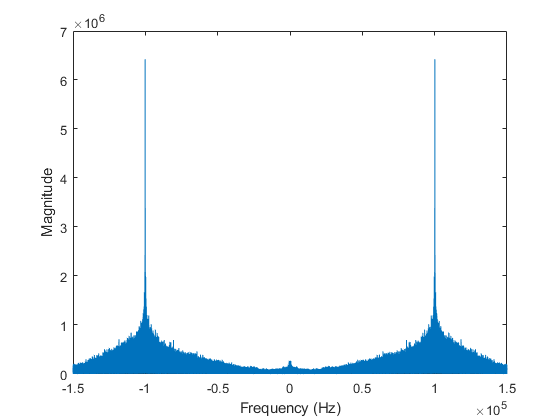

% Load FM data (collected via RTLSDRMatlabStream.m)
load("data/npr.mat");

% Plot y_I in the frequency domain
plot_FT(y_I, fs);
xlabel("Frequency (Hz)");
ylabel("Magnitude");

#### d.

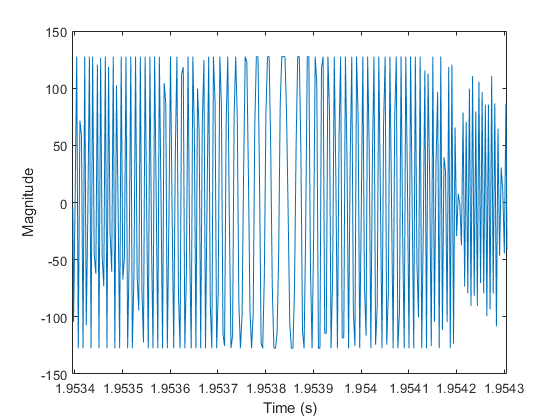

% Plot y_I in the time domain
t = linspace(0, length(y_I)/fs, length(y_I))';
plot(t, y_I)
xlabel("Time (s)");
ylabel("Magnitude");
xlim([1.953396 1.954306])

#### e.

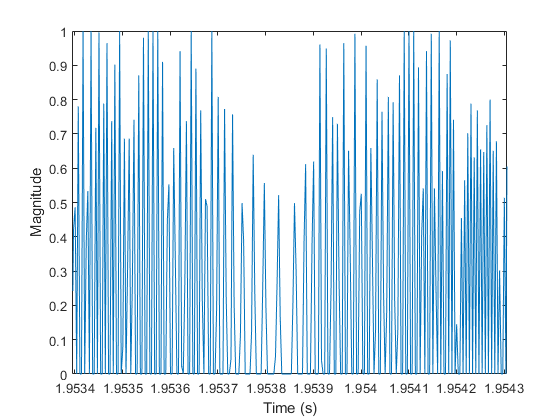

% Take the derivative of the signal
y_I_d = diff(y_I)./diff(t);

% Set negative values to zero
y_I_d(y_I_d < 0) = 0; 

% Rescale values between zero and one
y_I_d =  y_I_d / max(y_I_d);

% Plot resulting signal
plot(t(1:end-1), y_I_d);
xlabel("Time (s)");
ylabel("Magnitude");
xlim([1.953396 1.954306]);

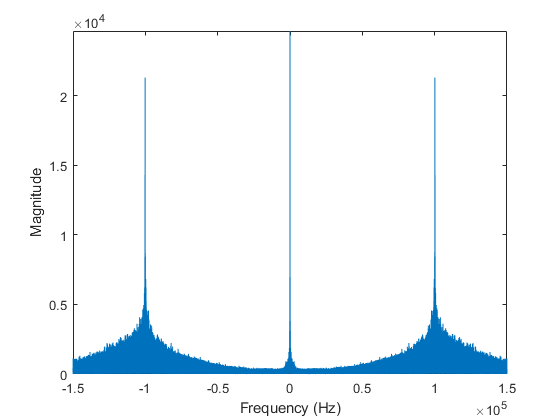

plot_FT(y_I_d, fs);
xlabel("Frequency (Hz)");
ylabel("Magnitude");
ylim([0 24675])

#### f.

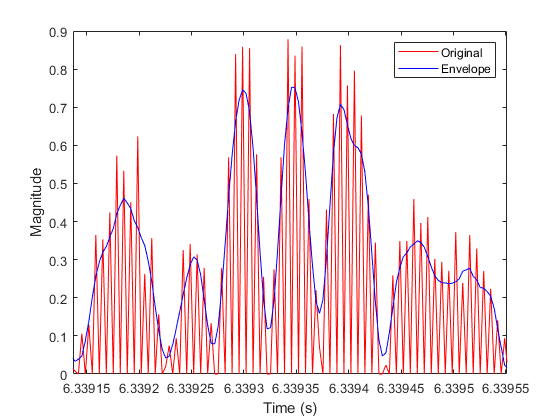

% Create low pass filter with sinc()
t_h = [-50:1:49]*(1/fs); % Creates 100 samples
w_lp = 41000; % cutoff frequency
h = 2*w_lp*sinc(2*w_lp*t_h);

% Convolve derivative of signal with low-pass filter and rescale
y_conv = conv(y_I_d, h,'same');
y_filt = y_conv / max(y_conv);

% Plot resulting signal; the new signal captures
% the envelope of the received signal.
t_filt = linspace(0, length(y_filt)/fs, length(y_filt));
figure()
plot(t(1:end-1), y_I_d, "Red", t_filt, y_filt, "Blue");
xlabel("Time (s)");
ylabel("Magnitude");
legend("Original", "Envelope")
xlim([6.339137 6.339551])

#### g.

% Subtract the mean
y_mean_sub = y_filt - mean(y_filt);

% Rescale the data to have a max value of 0.1
y_rescaled = rescale(y_mean_sub, -0.1, 0.1);

% Decimate the signal and play the sound
y_rescaled = decimate(y_rescaled, 4);
soundsc(y_rescaled, fs/4);
audiowrite("npr_decoded.wav", y_rescaled, fs/4);

### Exercise 2

#### b.

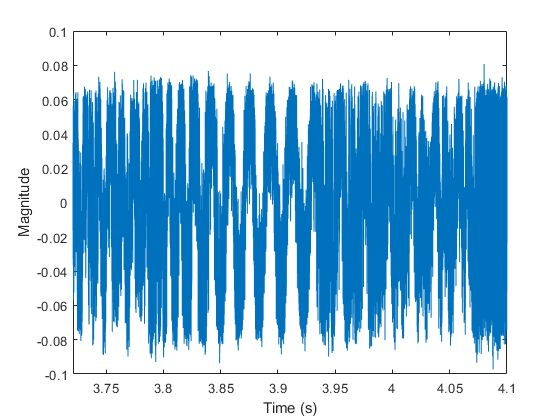

% Load FM data (collected via RTLSDRMatlabStream.m)
load("data/kiss108.mat");

% Decode message with provided equation in Exercise 2
t_Q = linspace(0, length(y_Q)/fs, length(y_Q))';
t_I = linspace(0, length(y_I)/fs, length(y_I))';
m_decoded = (diff(y_Q)./diff(t_Q)).*y_I(1:end-1) - (diff(y_I)./diff(t_I)).*y_Q(1:end-1);

% Subtract the mean from the signal
m_centered = m_decoded - mean(m_decoded);

% Normalize and plot resulting signal
m_normalized = m_centered * 0.1 ./ max(abs(m_centered));
plot(t_I(1:end-1), m_normalized);
xlabel("Time (s)");
ylabel("Magnitude");
xlim([0 10])
xlim([3.721 4.100])

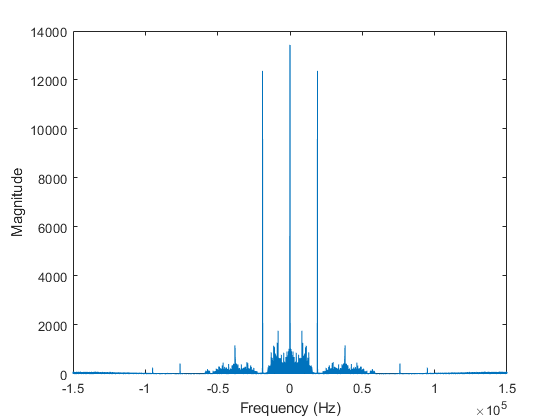

plot_FT(m_normalized, fs);
xlabel("Frequency (Hz)");
ylabel("Magnitude");

% Decimate and play sound
m_decimated = decimate(m_normalized, 4);
soundsc(m_decimated, fs/4);
audiowrite("kiss108_decoded.wav", m_decimated, fs/4);